# Jaccard (Intersection over union)

It's a popular method used to measure the accuracy of objects detector. Intersection over Union is simply an *evaluation metric*. Any algorithm that provides predicted bounding boxes as output can be evaluated using IoU.


$$J(A,B)=\frac{|A \cup B|}{|A \cap B| }=\frac{|A \cup B|}{|A| + |B| -  |A \cap B|}$$


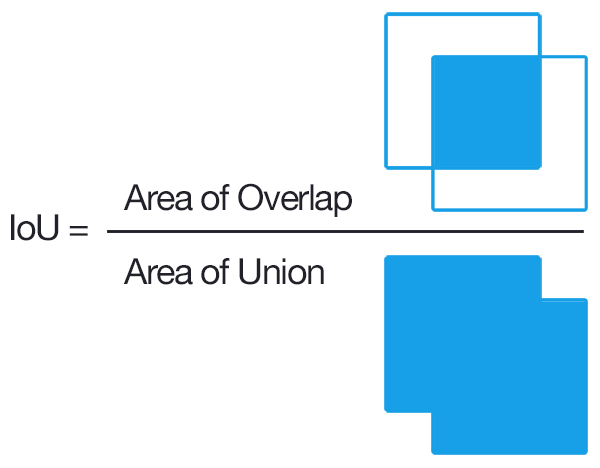

Normally the Jaccard (or IoU) needs the following inputs:

- The Ground-truth bounding box

- Predicted box from model

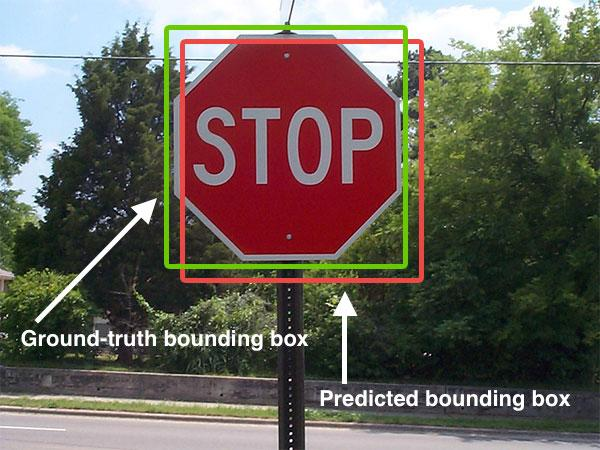

## References

- [IoU Jaccard python tutorial](http://www.pyimagesearch.com/2016/11/07/intersection-over-union-iou-for-object-detection/)

- [Jaccard Index Wikipedia](https://en.wikipedia.org/wiki/Jaccard_index)

- [MS Coco dataset format](http://mscoco.org/dataset/#format)

- [Matlab reference Box overlap ratio](https://uk.mathworks.com/help/vision/ref/bboxoverlapratio.html)

- [Hog + Svm object detection](http://www.pyimagesearch.com/2014/11/10/histogram-oriented-gradients-object-detection/)

## Example

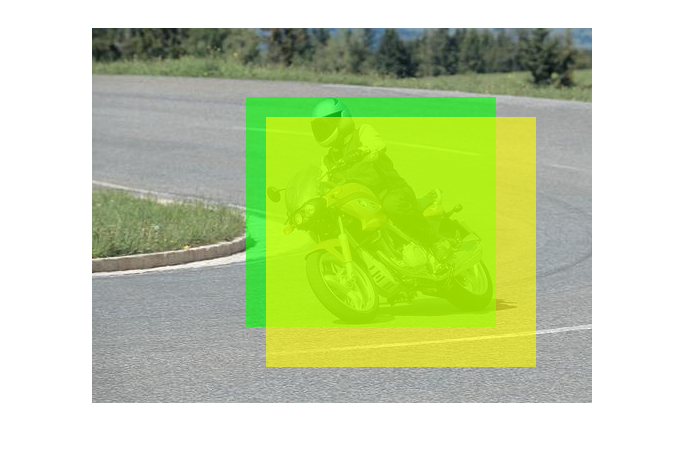

imgMoto = imread('learn/MatLiveScripts/imgs/MotoPascalVOC.jpg');
% Rect format is [x,y,width,height]
bboxA = [155,70,250,230];
%bboxB = bboxA + -1;
bboxB = bboxA + 20;
%bboxB = [155,70,220,210];
%bboxB = [105,70,220,210];

%Plot image with rects
RGB = insertShape(imgMoto,'FilledRectangle',bboxA,'Color','green');
RGB = insertShape(RGB,'FilledRectangle',bboxB,'Color','yellow');
imshow(RGB);

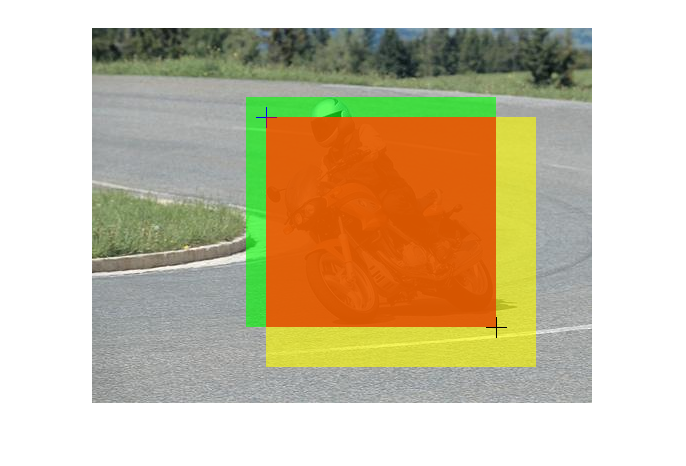


% Get (x,y,width,height) coordinates of intersection
xInter = max(bboxA(1), bboxB(1));
yInter = max(bboxA(2), bboxB(2));

% Convert rect format to (x1,y1,x2,y2), just to compute the width/height intersection
bboxA_conv = [bboxA(1),bboxA(2),bboxA(1)+bboxA(3),bboxA(2)+bboxA(4)];
bboxB_conv = [bboxB(1),bboxA(2),bboxB(1)+bboxB(3),bboxB(2)+bboxB(4)];
xB_inter = min(bboxA_conv(3),bboxB_conv(3));
yB_inter = min(bboxA_conv(4),bboxB_conv(4));

% Intersection width and height, ex: 250 - (265-250)
wInter = xB_inter - xInter;
hInter = yB_inter - yInter;

% Get intersection Area
AreaOverlap = wInter*hInter;

% Get the union Area
AreaUnion = ((bboxA(3)*bboxA(4)) + (bboxB(3)*bboxB(4))) - AreaOverlap;

% Add marker on image
RGB = insertMarker(RGB,[xInter, yInter],'color','blue','size',10);
RGB = insertMarker(RGB,[xB_inter, yB_inter],'color','black','size',10);
RGB = insertShape(RGB,'FilledRectangle',[xInter,yInter,wInter,hInter],'Color','red');
imshow(RGB);


% Get the IoU
IoURef = bboxOverlapRatio(bboxA,bboxB);
fprintf('Jaccard index or IoU(ref)=%3.2f\n',IoURef);

Jaccard index or IoU(ref)=0.63


IoU = AreaOverlap / single(AreaUnion);
fprintf('Jaccard index or IoU=%3.2f\n',IoU);

Jaccard index or IoU=0.63


IoU2 = IntersectOverUnion(bboxA,bboxB);
fprintf('Jaccard index or IoU=%3.2f\n',IoU2);

Jaccard index or IoU=0.63
